# **SISTEMAS DE CONTROL II**

#  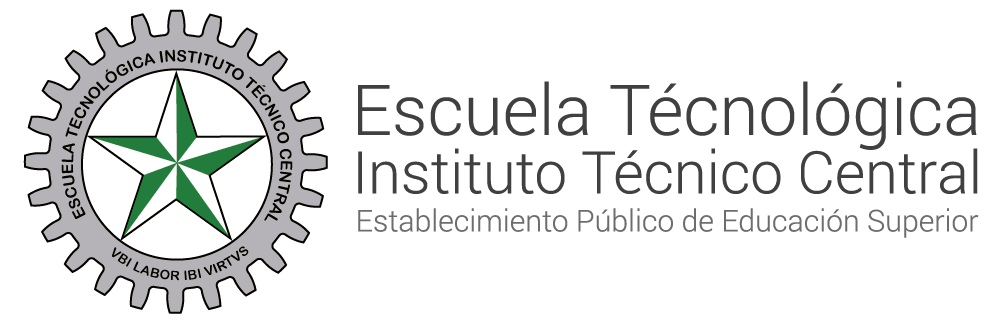

# **Transformada Z**

#### Autor ING. Jheyson Fabian Villavisan Buitrago MS.c

#### Coautor: Yenny Michel Wilches Zarate

**Objetivo:** El objetivo de esta clase es proporcionar a los estudiantes una **comprensión **profunda y práctica de la **Transformada Z** y su relevancia en el análisis y diseño de sistemas lineales e invariantes en el tiempo. Al finalizar la clase, los participantes estarán capacitados para:

Comprender los fundamentos teóricos de la Transformada Z y su relación con el análisis de señales y sistemas discretos.

Dominar los conceptos clave, como la región de convergencia, la relación entre la Transformada Z y la Transformada de Laplace, y las propiedades importantes de la Transformada Z.

# **Escalón unitario.**

- **Definición:**

El escalón unitario, denotado como $u\left(k\right)$, es una función definida como:


$$u\left(k\right)=\left\lbrace \begin{array}{ll}
0 & \mathrm{si}\;k<0\\
1 & \mathrm{si}\;k\ge 0
\end{array}\right.$$


## En sistemas discretos,** la transformada Z** se define como:


$$F\left(z\right)=\sum_{k=-\infty }^{\infty } f\left\lbrack k\right\rbrack z^{-k}$$


donde $f\left\lbrack k\right\rbrack$ representa los valores de la señal discreta en instantes $k$ (en este caso el escalón unitario). Para el escalón unitario discreto se tiene **que **$u\left(k\right)=1\;\textrm{para}\;k\ge 0$**:**

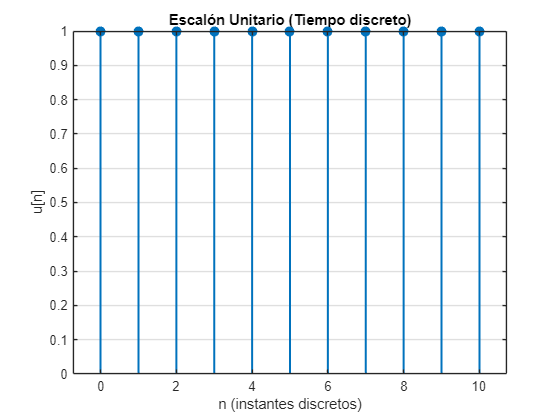

n = 0:10;
u = ones(size(n));
figure;
stem(n, u, 'filled', 'LineWidth', 1.5);
title('Escalón Unitario (Tiempo discreto)');
xlabel('n (instantes discretos)');
ylabel('u[n]');
grid on;


$$U\left(z\right)=\sum_{k=0}^{\infty } 1\cdot z^{-k}$$


Para resolver la trasnformada Z, se tiene en cuenta, la serie geométrica, la cual se define como: 


$$\sum_{n=0}^N r^n =\frac{r^{N+1} -1}{r-1}$$


Considerando lo anterior, se puede reescribir como:

$U\left(z\right)=\sum_{k=0}^{\infty } {\left(\frac{1}{z}\right)}^k$=$\frac{r^{N+1} -1}{r-1}$

Reemplazando $\frac{1}{z}$ en $r$ se obtiene:


$$U\left(z\right)=\frac{{\left(\frac{1}{z}\right)}^{\infty +1} -1}{\frac{1}{z}-1}$$


- Cuando ${\left(\frac{1}{z}\right)}^{\infty +1}$; Cuando se eleva un número $\left|\frac{1}{z}\right|<1$ a potencias crecientes $\left(\infty +1\right)$, el resultado converge hacia $0$. Esto se debe a que multiplicar un número menor que $1$ por sí mismo repetidamente da como resultado un valor cada vez más pequeño. Matemáticamente:


$$\lim_{n\longrightarrow \infty } {\left(\frac{1}{z}\right)}^n =0,\textrm{si}\;\left|\frac{1}{z}\right|<1$$


Por lo tanto:


$$U\left(z\right)=\frac{-1}{z^{-1} -1}$$


syms z n 
assume(abs(z) > 1);
r = 1/z; 
serie_geometrica = symsum(r^n, n, 0, Inf); 
formula_serie_geometrica = -1 / (r - 1)

$$formula\_serie\_geometrica = -\frac{1}{\frac{1}{z}-1}$$

Simplificando:


$$\begin{array}{l}
U\left(z\right)=\frac{1}{1-\frac{1}{z}}\\
U\left(z\right)=\frac{1}{\frac{z-1}{z}}\\
\mathit{\mathbf{U}}\left(\mathit{\mathbf{z}}\right)=\frac{\mathit{\mathbf{z}}}{\mathit{\mathbf{z}}-1}
\end{array}$$


U_z = simplify(formula_serie_geometrica)

$$U\_z = \frac{z}{z-1}$$